# Bounded Buffers and Stateful Servers

This script on average takes two minutes or so to run on my laptop. I appreciate your patience in advance. Wish you a merry Christmas break !

## 1. M/M/1/K Queue

### 1.1 Theoretical Analysis

The M/M/1/K can be seen as a truncated version of the M/M/1. In (Stewart, 2009), they use the birth-death process model with arrival rate $\lambda$ and service rate $\mu$, to study the structure of the state transition system. It becomes obvious that the Markov chain is finite and irreducible. Therefore ergodic. 

There are three scenarios in the flow balance equations for a set of state distributions $\pi_i \;$, where $0\le i\le K$


$$\lambda \pi_0 =\mu \pi_1$$


represent the token enters/leaves the **first slot** 


$$\left(\lambda +\mu \right)\pi_j =\lambda \pi_{j-1} +\mu \pi_{j+1}$$


represent the token enters/leaves any **slot in between** the first and the last slot, $0<j<K$


$${\mu \pi }_K =\lambda \pi_{K-1}$$


represent the token enters/leaves the **last slot**

Along with $\sum_{i=0}^K \pi_i =1$, we can compute the solution such that

$\pi_n =\left\lbrace \begin{array}{ll}
\frac{\left(1-\rho \right)\rho^n }{1-\rho^{K+1} } & \rho \not= 1\\
\frac{1}{K+1} & \rho =1
\end{array}\right.$         where $\rho =\frac{\lambda }{\mu }$ 

Because any entry attempt beyond the K slot will be rejected, we have proportion of dropped traffic representing $\lambda$$\pi_K$

So the effective arrival rate becomes $\lambda -\lambda$$\pi_K$, it gives us the effective **utilization** as


$$\frac{\lambda -\lambda \pi_K }{\mu }=\rho \left(1-\pi_K \right)$$


### 1.2 Simulation Setup

For the M/M/1/K building block layout, we introduce an output switch for directing the token to discard, as soon as the queue reach its full capacity. And redirect back to the queue when there is empty slot available.

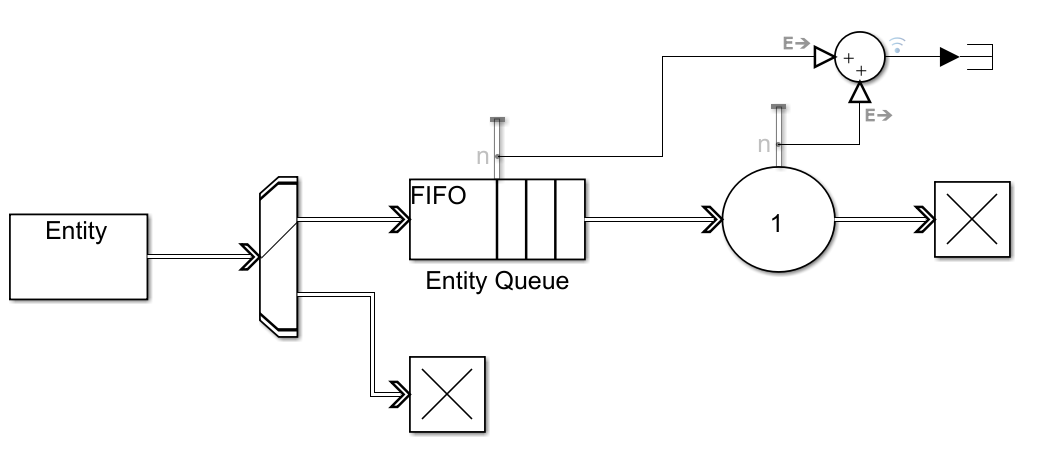

Setup shared variables for SimEvent

clear all; clc;
% initial declaration
global interServiceTime;
global interArrivalTime;
global stopTime;
global mySeed;
global capacity;

interServiceTime = Simulink.Parameter;
interArrivalTime = Simulink.Parameter;
stopTime = Simulink.Parameter;
mySeed = Simulink.Parameter;
capacity = Simulink.Parameter;

### 1.3 Probability of *n *Token in the System

The token distribution of a finite size queue is shown as below  

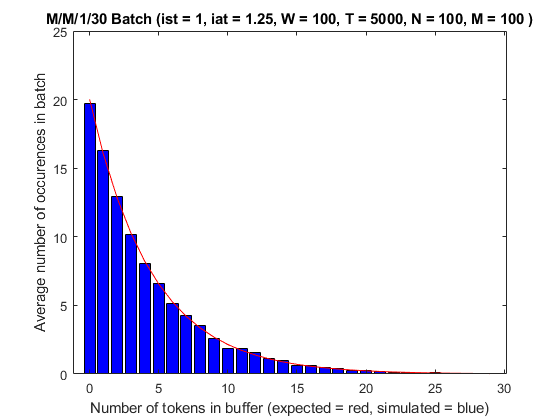

modelname = "MM1K";
% inter service time, inter arrival time 
ist = 1; iat = 1.25;
% warm-up period, batch size, #bins, #batches, samples/batch, fps
W = 100; T = 5000; C = 29; N = 100; M = 100; 
interServiceTime.Value = ist;
interArrivalTime.Value = iat;
capacity.Value = C;
stopTime = W+N*T;
mySeed.Value = 1925;

% compute expected distribution
rho = ist/iat;
p0 = (1-rho)/(1-(rho).^(C+1+1));
p = p0*rho.^[1:C];
expectedpdf = [p0 p];

SimOut = sim(modelname,'ReturnWorkspaceOutputs','on');
% Resample the run as a whole
thisrun = resample(SimOut.logsout{1}.Values,[W:T/(M-1):W+N*T-1],'zoh');
% Split into batches and determine counts for each batch
batchpoints = [W:T:W+N*T];
batchpdf = [];
for j = 1:N
    batchruns(j) = getsampleusingtime(thisrun,batchpoints(j),batchpoints(j+1));    
    batchpdf = [batchpdf;sum([batchruns(j).Data==[0:C-1],batchruns(j).Data>=C])];
end
% Determine the mean of each count over all batches as the estimate of the pdf
simulatedcount = [];
simulatedcount = [simulatedcount;mean(batchpdf)];

% Plot the pdf 
figure
bar([0:C],simulatedcount(:),"blue");
hold on;
plot([0:C],expectedpdf*M,"red");
title("M/M/1/"+(C+1)+...
    " Batch (ist = "+ist+", iat = "+iat+...
    ", W = "+W+", T = "+T+", N = "+N+", M = "+M+" )");
xlabel("Number of tokens in buffer (expected = red, simulated = blue)");
ylabel("Average number of occurences in batch");

From the above figure, we can see a smooth exponential decay of the number of tokens. In the M/M/1/$\infty$ queue, where there is a spike of numbers in the last bin, which represents the cumulation of the tail distribution. In contrary, the disappearing tail in the M/M/1/K queue reflect the fact that any extra token will not be accepted into the buffer if it is currently full loaded.

We can further perform a chi square goodness of fit test to verify our simulated data

chivalue = sum(((simulatedcount-(expectedpdf*N)).^2)./(expectedpdf*N),2);    
reject_H0 = chivalue > icdf('Chisquare',0.99,C)

reject_H0 = logical
   0


The test fails to reject H0, hence we are confident that these simulation data are correct.

## 2. MPEG Decoder

In this section we firstly discuss the formal analysis of the given Markov chain, to establish a steady tate distribution (if it exists), and the ergodicity (again, if it exists). Then we will determine the expected service rate and the expected variance, before comparing them with the simulation results.

### 2.1 Theoretical Analysis

We use $P_{\textrm{ij}} \;$to denote the probability of transition from state i to state j. Consider the n-step probability $P_{\textrm{ij}}^n$, by Chapman-Kolmogorov equations we can show that 


$$P_{\textrm{ij}}^{n+m} =\sum_{k=0}^{\infty } P_{\textrm{ik}}^n P_{\textrm{kj}}^m$$


where $n,m,i,j\ge 0$

This gives us the intuition that $P_{\textrm{ij}}^n$ is indeed an element of the *n*th power of transition probability matrix $P$.

The Markov chain of our MPEG-4 decoder is represented as the following: 

% Define "scene change" = state 1,
%        "action scene" = state 2,
%        "normal scene" = state 3,
%        "quiet scene" = state 4
P = [ 0.01 0.40 0.19 0.40;
      0.15 0.80 0.05 0.00;
      0.03 0.25 0.70 0.02;
      0.40 0.00 0.10 0.50 ];

To confirm the **irreducibility** of the n-states chain, we check whether every states are reachable within n-1 steps, that is, $P_{\textrm{ij}}^n >0$, for every states i, j. 

% check whether all states communicate after n-1 steps
Pn = (eye(size(P,2))+P)^(size(P,2)-1);
% check if all elements are nonzero
irreducible = any(Pn,'all')

irreducible = logical
   1


A Markov chain has a steady state distribution if 


$$p_j =\sum_{i=0}^{\infty } p_i P_{\textrm{ij}}$$


for j = 0, 1, 2,..

Since we know $\sum_{i=0}^{\infty } P_{\textrm{ji}} =1$, the above equation can be rearranged as 


$$p_j \sum_{i=0}^{\infty } P_{ji} =\sum_{i=0}^{\infty } p_i P_{ij}$$


which is known as the global balance equations (Bertsekas and Gallager, 1992). The solution of it will be the **steady state distribution**. Expressing in linear transformation form, it becomes clear that this is equivalent to solving the eigenvector $\pi$ when the eigenvalue $\lambda =1$, shown in the matrix equation below


$$\lambda \pi =P\pi$$


% solve the eigenvector (steady state distribution) that has lambda=1
vPi = linsolve([P'-eye(4);1,1,1,1],[0;0;0;0;1])

vPi =    0.134613167300819
   0.535858411161075
   0.213305661247550
   0.116222760290557


Since we have checked the Markov chain is irreducible, we can say that our steady state distribution is **unique**.

From the Perron-Frobenius Theorem (Horn and Johnson, 1985), a chain with a single recurrent communicating class has exactly one eigenvalue equal to `1.` All other eigenvalues have modulus less than or equal to `1`. We can check that by finding all the eigenvalues

% solve eigenvalues
lambda = eig(P')

lambda =  -0.256330712341353 + 0.000000000000000i
  1.000000000000000 + 0.000000000000000i
  0.633165356170676 + 0.059169969574544i
  0.633165356170676 - 0.059169969574544i


In fact, we only see one real eigenvalue which is equal to 1, and the remaining three are complex values with modulus less than 1. Hence the periodicity is equal to 1, in other words, we show that the chain is **aperiodic**. Besides, We can compute the convergence time to the steady state, by taking the second largest eigenvalue modulus.

% compute the second largest eigenvalue modulus (SLEM)
% convergence time = -1/log(SLEM)
slem = sort(abs(lambda),'descend');
tConverge = -1/log(slem(2))

tConverge =    2.209085177817617


This value means that the total variation distance between the initial distribution and the steady state distribution will decay by a factor of $e$ in approximately 2.209 steps. One could read up more about the precise definition of total variation distance in (Reiss, 1993). This convergence time will become useful when we determine the warm-up period for the batch method in the later discussion.

Now we have established that the Markov chain is aperiodic and converges to an unique steady state distribution in finite steps, we can conclude that the chain is **ergodic**. With this nice property, we know that the correlation from the initial condition will vanish after some countable steps. Hence, we can now justify the validity for the usage of long-run simulation in the following section, specifically, the batch method. 

### 2.2 Simulation Setup

Below is the building block layout of the MPEG-4 decoder, note that we decide not to limit the queue size, so there will be no frame loss.

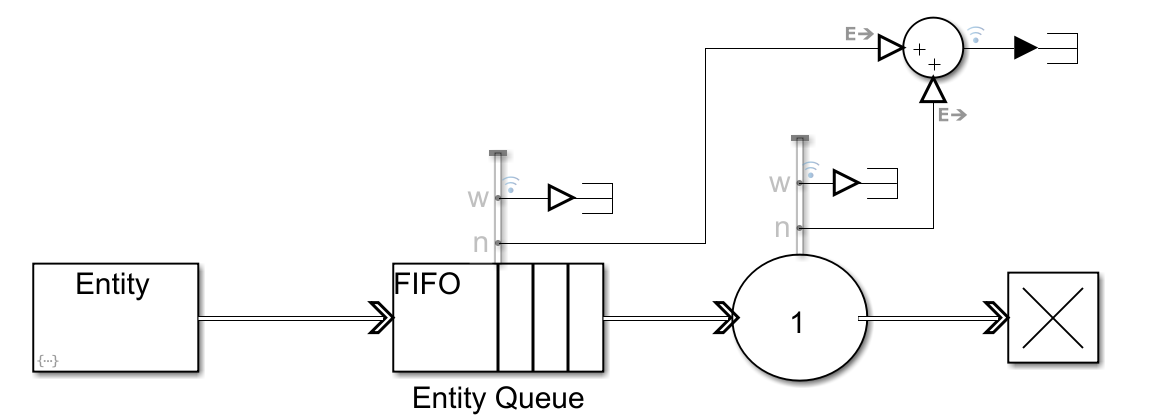

In order mimic the video stream of varying frame types, we configure the *"Entity Generator -> Event actions -> Generate"*, with the code shown in the snippet below

Additionally, we also set the service time to be the function of `entity.Size` in *"Entity Server -> Main". *Now we are ready to run the simulation.

### 2.3 Probability of *n *Frame in the System 

Now we will investigate the distribution of tokens (frames) in the system, for the case of 24 fps and 60 fps video. Firstly we compute the expected service rate and the variance of the expected service time as the following

% serve time for each state
tS = [0.02 0.015 0.01 0.005]';
% compute expected service rate
tSrv = vPi'*tS;
rSrv = 1/tSrv

rSrv =   74.380909500225130


% compute variance, i.e., E(X^2)-E(X)^2
var = vPi'*tS.^2-(tSrv)^2

var =      1.790007514065666e-05


Therefore we confirm that both 24 fps and 60 fps videos can be handled by our decoder, as both are less than the rate of 74.

The frame distribution for 24 fps is shown as the follows

global period;
modelname = "MPEG_Decoder";

% warm-up period, batch size, #bins, #batches, samples/batch, fps
W = 200; T = 500; C = 2; N = 50; M = 100; fps = 24;

period = 1/fps;
stopTime = W+N*T;
mySeed.Value = mySeed.Value+1;

% compute utilization
util = fps/rSrv;
% compute expected distribution
expectedpdf = [1-util util 0 ];

SimOut = sim(modelname,'ReturnWorkspaceOutputs','on');
% Resample the run as a whole
thisrun = resample(SimOut.logsout{3}.Values,[W:T/(M-1):W+N*T-1],'zoh');
% Split into batches and determine counts for each batch
batchpoints = [W:T:W+N*T];
batchpdf = [];
for j = 1:N
    batchruns(j) = getsampleusingtime(thisrun,batchpoints(j),batchpoints(j+1));    
    batchpdf = [batchpdf;sum([batchruns(j).Data==[0:C-1],batchruns(j).Data>=C])];
end
% Determine the mean of each count over all batches as the estimate of the pdf
simulatedcount = [];
simulatedcount = [simulatedcount;mean(batchpdf)];

Note that the warm up period is conservatively chosen to be approximately 100 times of the convergence time found earlier in Section 2.1. For the expected distribution, we notice that every states of the decoder have the service rate > 24, suggesting that the probability of having more than one token in the system at any given time is zero. We can plot the distribution as the one below 

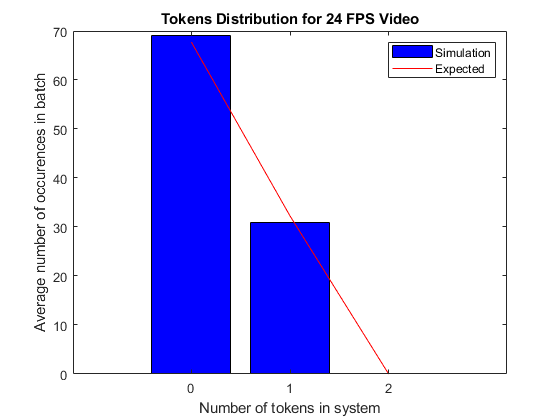

figure
bar([0:C],simulatedcount(:),"blue");
hold on;
plot([0:C],expectedpdf*M,"red");
xlabel("Number of tokens in system");
ylabel("Average number of occurences in batch");
legend('Simulation','Expected');
title("Tokens Distribution for 24 FPS Video");
drawnow;

We can compute for 60 fps video in a similar fashion

% update fps
fps = 60;
period = 1/fps;
% update #bins
C = 3;
% update seed
mySeed.Value = mySeed.Value+1;

% compute utilization
util = fps/rSrv;
% compute expected distribution, Pr(#tokens>3) is negligible
expectedpdf = [1-util util*(1-vPi(1)) (util^2)*vPi(1) (util^3)*vPi(1)^2];
SimOut = sim(modelname,'ReturnWorkspaceOutputs','on');
% Resample the run as a whole
thisrun = resample(SimOut.logsout{3}.Values,[W:T/(M-1):W+N*T-1],'zoh');
% Split into batches and determine counts for each batch
batchpoints = [W:T:W+N*T];
batchpdf = [];
for j = 1:N
    batchruns(j) = getsampleusingtime(thisrun,batchpoints(j),batchpoints(j+1));    
    batchpdf = [batchpdf;sum([batchruns(j).Data==[0:C-1],batchruns(j).Data>=C])];
end
% Determine the mean of each count over all batches as the estimate of the pdf
simulatedcount = [];
simulatedcount = [simulatedcount;mean(batchpdf)];

Note that now we have actually one state, namely the "scene change" state (state 1), that is slower than 60 fps. Meaning that there is now a chance for tokens to queue up in the system, provided that the preceding tokens were "scene change" frame. 

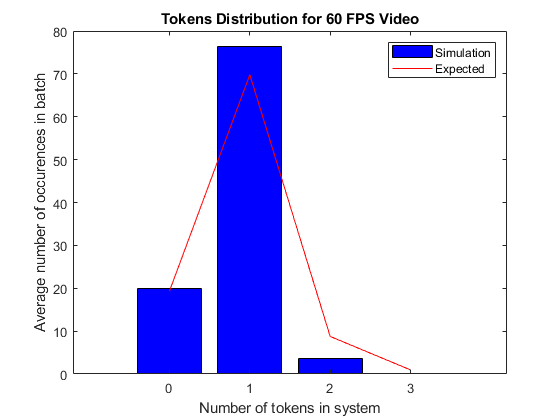

figure
bar([0:C],simulatedcount(:),"blue");
hold on;
plot([0:C],expectedpdf*M,"red");
title("Tokens Distribution for 60 FPS Video");
xlabel("Number of tokens in system");
ylabel("Average number of occurences in batch");
legend('Simulation','Expected');
drawnow;

### 2.4 Service Time

We now want to check whether the simulated service time is consistent with our expected value. With a sufficient number of batches, we expect the batch means to be normally distributed, according to the Central Limit Theorem. This hypothesis can be tested against the expected mean as the following  

thisrun = SimOut.logsout{2}.Values;
% Resample the run as a whole
thisrun = resample(thisrun,[W:T/(M-1):W+N*T-1],'zoh');
% Split into batches
batchpoints = [W:T:W+N*T];
% compute means for each batch
for j = 1:N
    batchruns(j) = getsampleusingtime(thisrun,batchpoints(j),batchpoints(j+1));    
    tdelta = batchruns(j).TimeInfo.End-batchruns(j).TimeInfo.Start;
    dt = diff(batchruns(j).Time);
    vbatch(j) = (batchruns(j).Data)'*[dt;0]/tdelta;
end
% perform hypothesis testing with 99% confidence level
z = sqrt(N).*(mean(vbatch)-tSrv)/sqrt(var);
reject_H0 = cdf("Normal",-abs(z),0,1)+(1-cdf("Normal",abs(z),0,1)) < 0.01

reject_H0 = logical
   0


We see that the z-test fails to reject H0. Hence we are confident about the simulated service time.

### 2.5 Latency

Under this context, we consider the latency of service as the duration a frame waiting in the queue buffer. Here we attempt show a theoretical analysis of the expected value. We observe that for any video under 66 fps (i.e., 15 msec period), only the "scene change" state in the decoder would contribute to delay. Hence we argue that by taking the summation of all the probabilities of consecutive "scene change" occurrences, we are able to infer the expected queue length $L_q$ as


$$L_q =\sum_{k=1}^{\infty } {\pi_1 }^k \left(\frac{1}{\mu_1 }-\frac{1}{\lambda }\right)k\lambda$$


where $\pi_1$ is the steady state probability of "scene change", $\mu_1$ is the service rate of the "scene change" state, and $\lambda$ is the arrival rate

By Little's Theorem, we have the average waiting time $W_q =\frac{L_q }{\lambda }$

The numerical value of $W_q$ can be computed such that 

syms k
lq = symsum((vPi(1)^k)*(tS(1)-1/fps)*k,k,1,Inf);
Wq = cast(lq,'double')

Wq =      5.991640150053441e-04


We can compare this value with the simulated resultes

thisrun = SimOut.logsout{1}.Values;
% Resample the run as a whole
thisrun = resample(thisrun,[W:T/(M-1):W+N*T-1],'zoh');
% Split into batches
batchpoints = [W:T:W+N*T];
% compute means for each batch
for j = 1:N
    batchruns(j) = getsampleusingtime(thisrun,batchpoints(j),batchpoints(j+1));    
    tdelta = batchruns(j).TimeInfo.End-batchruns(j).TimeInfo.Start;
    dt = diff(batchruns(j).Time);
    vbatch(j) = (batchruns(j).Data)'*[dt;0]/tdelta;
end
bWq = mean(vbatch)

bWq =      5.726415069396551e-04


We see that although the two values between the theoretical and experimental are close, but there is still a noticeable discrepancy, as if the value derived from the equations is overestimated. Suggesting further investigation is needed. 

## 3. Other Remarks

Although we have established the reasoning to adopt long-run simulation in Section 2.1. It is still worth to verify whether the batch means display any autocorrelation. Hence, below we show the lag-1 scatter plot. Unexpectedly there is a visible trend on the plot, implying the batches are in fact not i.i.d (Alexopoulos and Seila, 1996). At this moment of writing, the exact reason of this is now known to us yet. Therefore, an urgent investigation is required. 

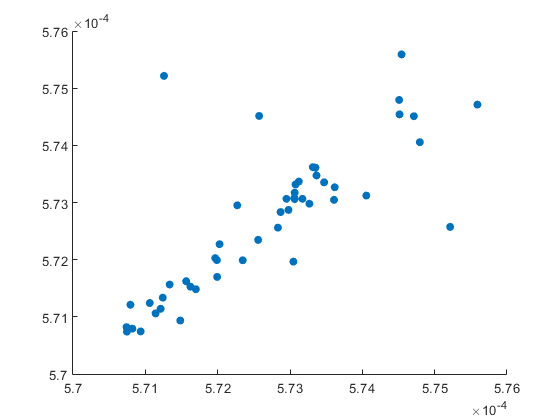

lag = 1;
X = vbatch(1:end-lag);
Y = vbatch(1+lag:end);
figure
scatter(X,Y,'filled');

## 4. Reflection

Throughout this report, we strive to provide a formal analysis along with every simulation results, in which will allow the reader to study and compare to. Some of the equation derivations are speculative at best, such as the formula for expected average waiting time given in Section 2.4, or the expected distribution of 60 fps video given in Section 2.3. These data agree with the results of simulations to a limited extent (fairly close, but not exact). Despite that, we believe they still offer some values (or do they?) as reference purpose.

One more thing worth mentioning is that a fellow student, Nikola Felkaroski, brought up a strange observation that some tokens in the non-empty buffer/server, have been repeatedly sampled. In consequence, this would affect our statistics of the token distribution under a single-run simulation. At the time being, We are still in search of the root cause. Nevertheless, Nikola's remarkable insight is greatly appreciated.  

## 5. Bibliography

- Stewart, W. J. (2009). *Probability, Markov chains, queues, and simulation: the mathematical basis of performance modeling*. Princeton university press.

- Bertsekas, D. P., Gallager, R. G., & Humblet, P. (1992). *Data networks* (Vol. 2). New Jersey: Prentice-Hall International.

- Horn, R. A., & Johnson, C. R. (1985). *Matrix analysis*. Cambridge university press.

- Reiss, R. D. (1993). Poisson and Cox Processes. In *A Course on Point Processes* (pp. 45-76). Springer, New York, NY.

- Alexopoulos, C., & Seila, A. F. (1996, December). Implementing the batch means method in simulation experiments. In *Proceedings Winter Simulation Conference* (pp. 214-221). IEEE.